clc;clear;

mdlNames=[
    "triangular_25rules"
    "gaussian_product"
    "triangular_49rules"
    ];

## Prepare fuzzy controller

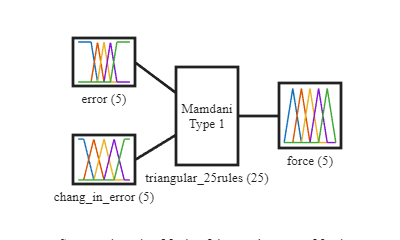

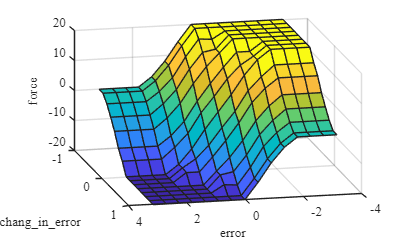

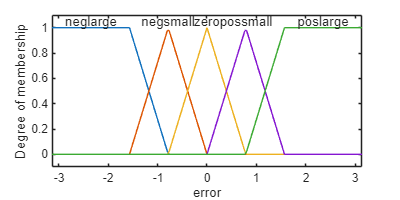

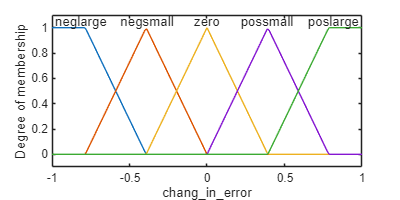

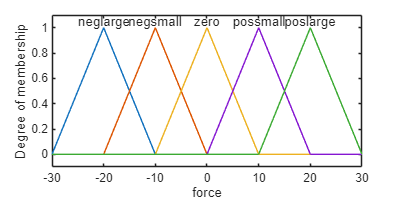

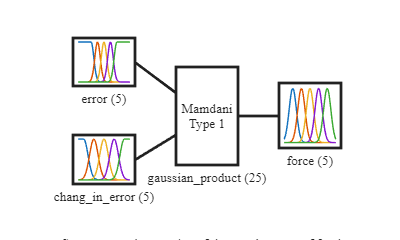

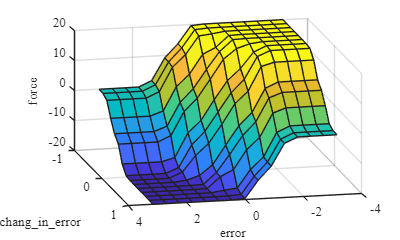

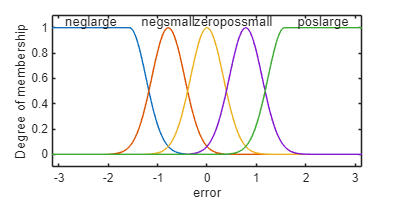

fis = cell(1,length(mdlNames));
for i = 1:length(mdlNames)
    fis{i} = readfis("assets/"+mdlNames(i));
    visualizeFIS(fis{i},mdlNames(i));
end

## Set derivative gain

deriv_gain_set = [
    % g0 g1 h
    [1 1 1]
    [1 0.1 1]
    [2 0.1 1]
    [2 0.1 5]
    [5 1 1]
    ];

## Start Simulink

% open_system("pendulum_system");
y = cell(length(deriv_gain_set),length(mdlNames));
u = cell(length(deriv_gain_set),length(mdlNames));

for i = 1:length(deriv_gain_set)
    g0 = deriv_gain_set(i,1);
    g1 = deriv_gain_set(i,2);
    h = deriv_gain_set(i,3);
    for j = 1:length(mdlNames)
        [y{i,j},u{i,j}]=simPendulumSystem(fis{j},g0,g1,h);
    end
end

## Plot data

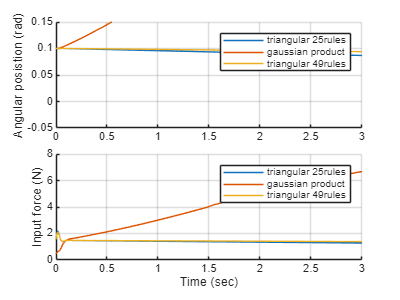

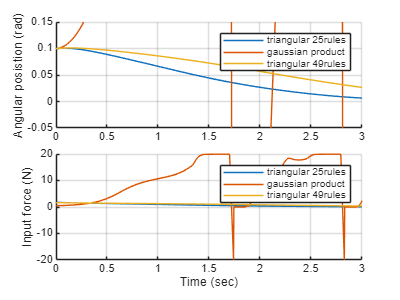

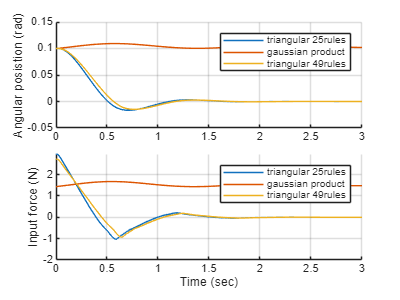

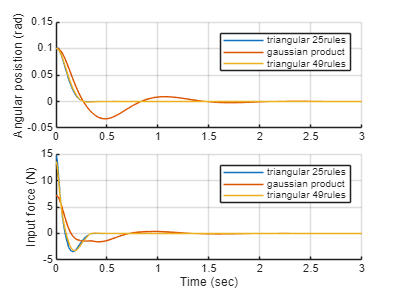

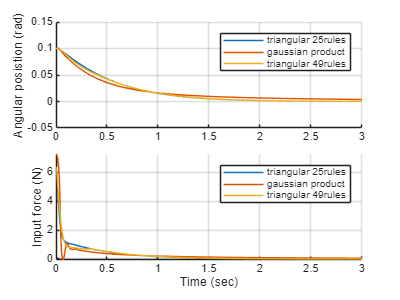

for i = 1:length(deriv_gain_set)
    fig = figure('Position',[0 0 400 300],'Units','points');
    fontname(fig,'TeXGyreTermes');
    fontsize(fig,10,"points");
    tiledlayout("vertical","TileSpacing","compact")

    % Angular position
    nexttile
    hold on;
    for j = 1:1:length(mdlNames)
        plot(y{i,j},"Time (sec)","Angular posistion (rad)");
    end
    hold off;
    xlabel("");
    ylim([-0.05 0.15]);
    legend(mdlNames.replace("_"," "));
    grid on;

    % Input force
    nexttile
    hold on;
    for j = 1:1:length(mdlNames)
        plot(u{i,j},"Time (sec)","Input force (N)");
    end
    hold off;
    legend(mdlNames.replace("_"," "));
    grid on;

    settingstr = "sim_"+num2str(deriv_gain_set(i,1))+"_"+num2str(deriv_gain_set(i,2))+"_"+num2str(deriv_gain_set(i,3));
    exportgraphics(fig,"figures/"+settingstr+".svg");

end